## **Module 1:**

## **Part 1:**

events=importStormData("StormEvents_2013.csv");
monthOrder=["January", "February", "March", "April", "May", "June", "July",...
    "August", "September", "October", "November", "December"];
events.Month=reordercats(events.Month,monthOrder);
events.Property_Cost(ismissing(events.Property_Cost))=0;
events.Crop_Cost(ismissing(events.Crop_Cost))=0;
events.Total_Damage=events.Property_Cost+events.Crop_Cost;
events

events = 59985×17 table
     Month         Event_Type          Begin_Date_Time      Timezone    Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    

## **Part 2:**

minDamage =640000;

Controlling with numeric sider.

tornadoes=events(events.Total_Damage>=minDamage & events.Event_Type=="Tornado",:)

tornadoes = 61×17 table
     Month      Event_Type      Begin_Date_Time      Timezone    Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                            Episode_Narrative                                             

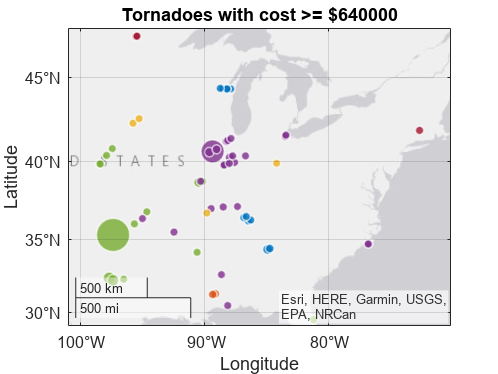

geobubble(tornadoes.Begin_Lat,tornadoes.End_Lon,tornadoes.Total_Damage,tornadoes.Month);
title("Tornadoes with cost >= $"+ minDamage)

Another Choice

eventMonth="January";
tornadoes=events(events.Event_Type=="Tornado",:)

tornadoes = 1053×17 table
     Month     Event_Type      Begin_Date_Time      Timezone    Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        Episode_Narrative                

tornadoes=events(events.Month==eventMonth,:)

tornadoes = 5305×17 table
     Month        Event_Type          Begin_Date_Time      Timezone    Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                      Episode_Narrative                                                                                                                           

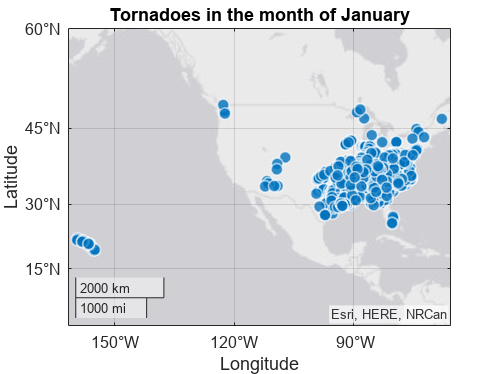

geobubble(tornadoes.Begin_Lat,tornadoes.Begin_Lon)
title("Tornadoes in the month of " + eventMonth)

## **Part 3:**

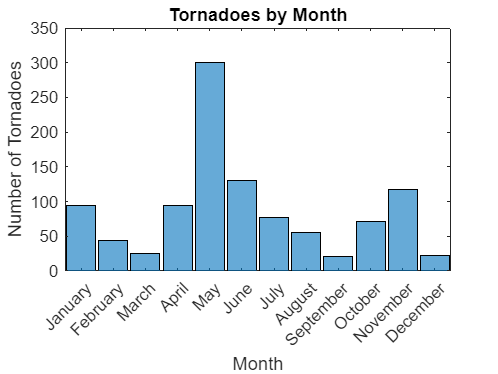

tornadoes=events(events.Event_Type=="Tornado",:);
histogram(tornadoes.Month)
title("Tornadoes by Month")
xlabel("Month")
ylabel("Number of Tornadoes")

Total Damage by Month:

stat="median"

stat = "median"

tornadoes=events(events.Event_Type=="Tornado",:);
cost=groupsummary(tornadoes,"Month",stat,"Total_Damage")

cost = 12×3 table
      Month      GroupCount    median_Total_Damage
    _________    __________    ___________________

    January          95               80000       
    February         44               12500       
    March            25               25000       
    April            94               10000       
    May             301                   0       
    June            131                   0       
    July             77                5000       
    August           55                   0       
    September        21                1000       
    October          71               15000       
    November        117               50000       
    December         22               1e+05       


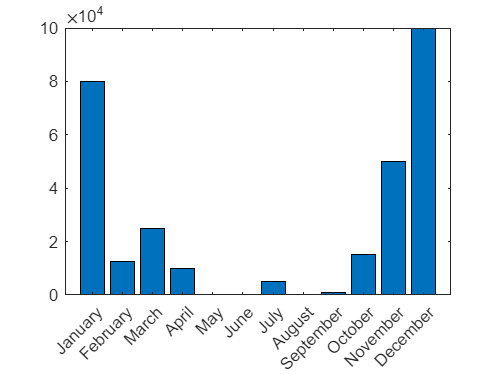

bar(cost.Month,cost{:,end})

## **Module 4:**

x=groupsummary(events,"Month",{"Max","Min","Mean"},"Total_Damage");
x(x.Month=="January",:);
% cost=groupsummary(events,"Month","Sum","Total_Cost")
% plot(cost.Month,cost{:,end},color="red",LineStyle="--",Marker="o",MarkerSize=10)

Pdf File

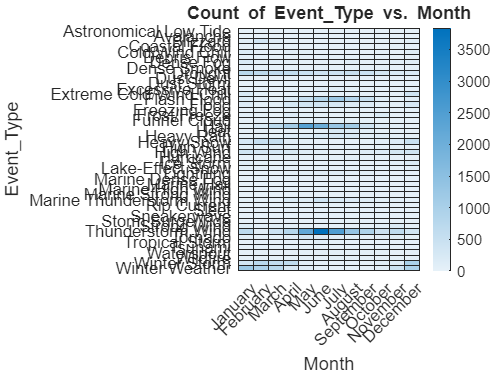

heatmap(events,"Month","Event_Type")

hind=events(events.Event_Type=="Hail",:)

hind = 9625×17 table
    Month    Event_Type      Begin_Date_Time      Timezone    Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                          Episode_Narrative                                                                                                                                                                         Event_Narrative                                    Total_Damage
    _____    __________    ___________________</

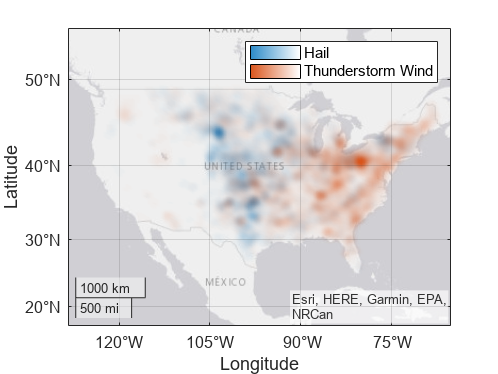

geodensityplot(hind.Begin_Lat,hind.Begin_Lon)
geolimits([17.0 55.2],[-128.0 -65.6])
hold on
TWind=events.Event_Type=="Thunderstorm Wind";
geodensityplot(events.Begin_Lat(TWind),events.Begin_Lon(TWind))
hold off
legend(["Hail","Thunderstorm Wind"])